clear;
clc;

m=200; M=10000; d=3; g=9.8;
%Condiciones iniciales
Z0=0*pi/180; Zp0=0;
%Fuerza estática a superar en el instante inicial
F0=2*(M+m)*g*cos(Z0)/cos(Z0/2);
%Fuerza aplicada (por ejemplo)
F=F0+20000;
%Posición final deseada
Zf=45/180*pi;

t0=0; tp0=3;

vdp=@(t,y)[y(2);(F*d*cos(y(1)/2)-2*(M+m)*g*d*cos(y(1))+4*y(2)^2*M*d^2*sin(y(1))*cos(y(1)))/(4*d^2*(2/3*m+M*(cos(y(1)))^2))];

opt=odeset('events',@stop);

[t,y]=ode45(vdp,[t0 tp0],[Z0;Zp0],opt);

%Aceleración del sistema
Zpp=(F*d*cos(y(:,1)/2)-2*(M+m)*g*d*cos(y(:,1))+4*y(:,2).^2*M*d^2.*sin(y(:,1)).*cos(y(:,1)))./(4*d^2*(2/3*m+M*(cos(y(:,1))).^2));
%Cálculo altura
h = 2*d.*sin(y(:,1));
%Cálculo velocidad
v = 2*y(:,2)*d.*cos(y(:,1));
%Cálculo potencia

pot = y(:,2)*F*d.*cos(y(:,1)/2);

figure;
plot(t,y(:,1),t,y(:,2),'--',t,Zpp,'r');
xlabel('t');
legend('\theta(rad)','\theta'' (rad/s)','\theta"(rad/s)','location','northwest');

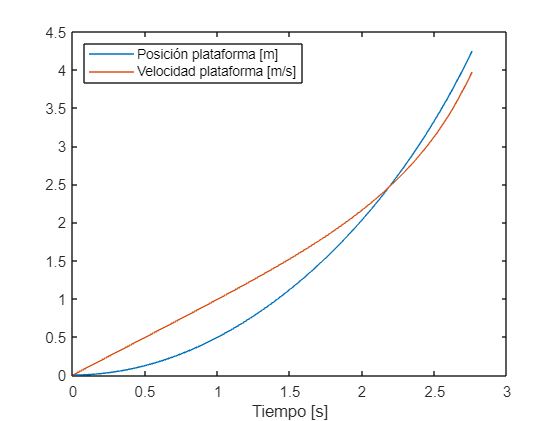


figure;
plot(t,h,t,v);
legend('Posición plataforma [m]', 'Velocidad plataforma [m/s]','location','northwest');
xlabel('Tiempo [s]');

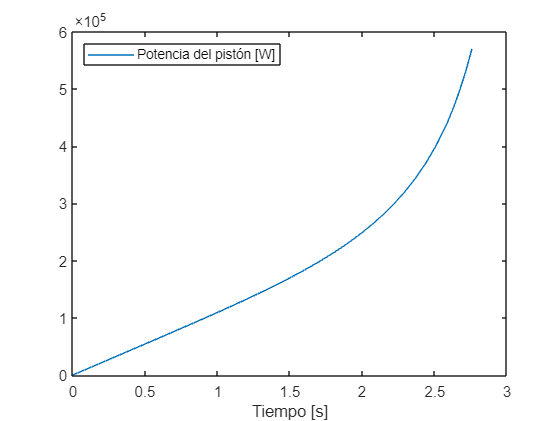


figure;
plot(t,pot);
legend('Potencia del pistón [W]','location','northwest');
xlabel('Tiempo [s]');


%Cálculo potencia pistón

W = trapz(pot)

W = 7.6576e+06

function [v,i,d]=stop(t,y);
v=y(1)-45/180*pi;
i=1;
d=1;
end